## Dane wejściowe

clear all
load("data\mass_data.mat","Iyy","Mass")
load("data\enviroment_data.mat","dynamic_pressure","v_sound")
load("data\wing_geometry.mat","S","MAC")
load("data\flight_cases_data.mat", "mach")
load("data\longitudinal_data.mat")
load("data\longitudinal_dimnsional_derivatives.mat")


## Wykresownik

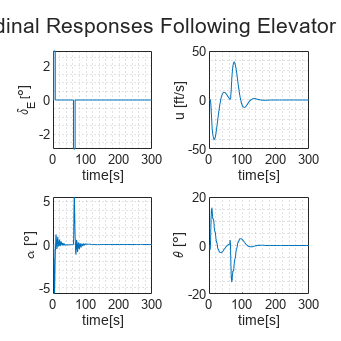

global i
i=1;
global o
o=2;
grapher(1,2,'dla_lukasza.jpg')

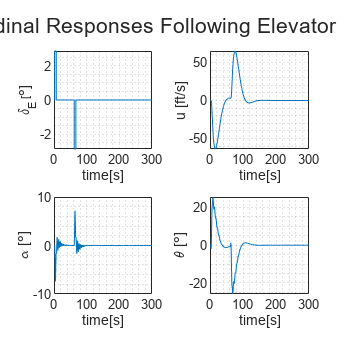

grapher(1,3,'dla_janka.jpg')

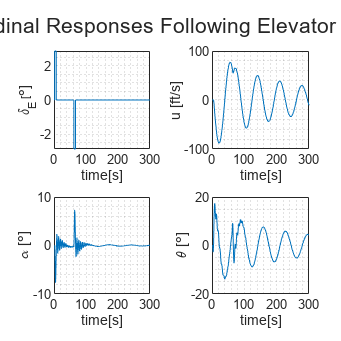

grapher(2,4,'dla_michala.jpg')

function grapher(row1,col1,file_namee)
        global i
        i=row1;
        global o
        o=col1;
        wyk= figure;
        wyk.Position=[0 0 1000 1000];
        wyk=tiledlayout(2,2,"TileSpacing","compact");
        title(wyk,'Longitudinal Responses Following Elevator Maneuver')
        simIn = Simulink.SimulationInput('dynamic_calc');
        simIn = setModelParameter(simIn,'StartTime','0','StopTime','300','FixedStep','0.001');
        runIDs = Simulink.sdi.getAllRunIDs;
        runID = runIDs(end);
        dataset = Simulink.sdi.exportRun(runID);
        out = sim(simIn);
        u_t = out.u;
        alfa_t = out.alfa;
        theta_t=out.theta;
        delta_t=out.delta;
        nexttile
        plot(u_t.time,delta_t.Data)
        xlabel('time[s]')
        ylabel('\delta_E [\circ]')
        grid minor
        nexttile
        plot(u_t.time,u_t.Data)
        xlabel('time[s]')
        ylabel('u [ft/s]')
        grid minor
        nexttile
        plot(alfa_t.time,alfa_t.Data)
        xlabel('time[s]')
        ylabel('\alpha [\circ]')
        grid minor
        nexttile
        plot(theta_t.time,theta_t.Data)
        xlabel('time[s]')
        ylabel('\theta [\circ]')
        grid minor
        saveas(wyk,file_namee);
end